#### Full System:


$$R_{growth}=  (\psi_g + \psi_d)\cdot\frac{(\eta_AA + 1)^{n_1} + \left(\frac{P_R}{\delta}\right)^{n_1}}{(\eta_B B_{ext} + 1)(\eta_AA+ 1)^{n_1}+ \left( \frac{P_R}{\delta} \right)^{n_1} } - \psi_d-\psi_C \cdot \frac{\eta_{I} I \cdot  \left(\frac{P_C}{\delta}\right)^{n_2}}{\eta_{I}I \cdot \left(\frac{P_C}{\delta}\right)^{n_2}+(\eta_AA +1)^{n_2}} $$



$$\frac{\textrm{dy}}{\textrm{dt}}=R_{\textrm{growth}\;} \cdot y\left(1-y^{\upsilon } \right)$$


#### Parameter list:

x(1) = $\psi_g$=$\delta$

x(2) = $\psi_C$

x(3) = $P_C \cdot {\left(\eta_I \cdot I\right)}^{\frac{1}{n_2 }}$

x(4) = $\psi_d$

x(5) = $\eta_B B_{\textrm{ext}}$

x(6) = $P_R$

x(7) = $n_1$

x(8) = $n_2$

#### Load data:

clear all; close all;
addpath('./MatlabFuncs/')

load('Data/Param_Fit2.mat', 'x_both'); %%mac syntax
% load('Data\Param_Fit2.mat', 'x_both');
load('Data/Param_Fit3.mat', 'x_all'); %%mac syntax
% load('Param_Fit3.mat', 'x_all');



run('./MatlabFuncs/FuncGenerator.m');

#### Set known values:

param = x_all; %x_both;

% AP1903 and blasticidin concentration
B_ext0 = 50; %ug
AP0 = 20; %uM

% BLASTR and iCasp protein expression
P_R0 = param(6);
eta_I =.01 ;% assumed
P_C0 =  param(3)./((eta_I.* AP0).^(1./param(8)));

% Logistic function parameters
N_cap = 1;
Nu1 = 100 ./ (N_cap * 24); %Ncap cells secrete 100uM auxin a day 
Delta1 = log(2) / 24; %24 hour half life
A_cap = Nu1.*N_cap./Delta1;
nu = 3.14; %Correction for generalized logistic dynmaics

%enumerate varied Parameters
power_AP = linspace3(-1,log10(AP0),log10(100),12);
power_B = linspace3(-1,log10(B_ext0),log10(300),12);
power_R = linspace3(log10(P_R0)-1,log10(P_R0),log10(P_R0)+1,3);
power_C = linspace3(log10(P_C0)-1,log10(P_C0),log10(P_C0)+1,3);
[AP,B_ext,P_R,P_C] = ndgrid(10.^power_AP,10.^power_B,10.^power_R,10.^power_C);


#### Parameter Sweep Set up: 

%Initiate variables as symbols 
syms A positive
syms N positive


%Initiate Data arrays
Pure_Death = [];
Pure_Growth = [];
mono_unstable =[];
mono_stable = [];
bi_stable = [];
bi_unstable = [];

ratebi_stable = [];
ratebi_unstable = [];
ratemono_stable = [];
ratemono_unstable = [];
ratePure_Death = [];
ratePure_Growth = [];

#### Symbolic Expression of rate function:

tic
parfor i = 1:numel(AP)
    % Factor in the AP1903 and Blasticidin concentration, and protein expressions into the parameters
    theta =param;
    theta(3) = param(3).* (P_C(i) ./ P_C0) .* (AP(i) ./ AP0).^(1/param(8));
    theta(5) = param(5) .* (B_ext(i) ./ B_ext0);
    theta(6) = param(6) .* (P_R(i) ./ P_R0);   
    
    rate_exp(i) = rate_comb(theta, A); 
    d_rate = jacobian(rate_exp(i), A);
    A_peak{i} = double(vpasolve(d_rate == 0,A,[0,A_cap]))
end  

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).



elapsed1 = toc;
disp(elapsed1./60.*minutes) 

   4.0313 min



#### Solve for equilbrium points of rate function :

n = 3;

parfor i = 1:numel(AP)    
if  not(isempty(A_peak{i}))
    window = linspace3(0,A_peak{i},A_cap,3);
   eq_ps = [];
    for a = 2:n
       left = window(a-1);
       right = window(a); 
       eq_p = vpasolve(rate_exp(i) == 0,A,[left right],'Random',true); 
       eq_ps = [eq_ps;eq_p]
    end
    
    sols{i} = eq_ps;
else
    sols{i} = vpasolve(rate_exp(i) == 0,A,[0,A_cap],'Random',true);
    
end
    
end
    

elapsed2 = toc;
disp(elapsed2./60.*minutes)  

   20.393 min



#### Stabilty analysis:

%Symbolic Expression for differential equation for auxin
d_A = Nu1*N - Delta1*A;
parfor i = 1:numel(AP)

    A_eq{i} = sort(unique(double(sols{i})));
   
        
    % Store system parameters with 0 eq. points (Pure Death)
    
    rate_t = double(subs(rate_exp(i),'A',20));
    
    if isempty(A_eq{i}) && rate_t < 0 
        Pure_Death = [Pure_Death;[AP(i),B_ext(i),P_R(i),P_C(i)]];
        ratePure_Death = [ratePure_Death;rate_exp(i)]
    else
        Pure_Growth = [Pure_Growth;[AP(i),B_ext(i),P_R(i),P_C(i)]];
        ratePure_Growth  = [ratePure_Growth ;rate_exp(i)]
        
    end
    
   %Symbolic Expression for differential equation for cell population
    d_N = rate_exp(i)* N * (1 - (N / N_cap)^nu);
    
   %Construct Jacobian
    J = jacobian([d_A, d_N], [A, N]); 
    
    % Store system parameters with 1 eq. point (monophasic)
    if length(A_eq{i}) == 1 
          
         %find eigen-values at eq. point
        J_mono = subs(J, {A, N}, {A_eq{i}, Delta1.*A_eq{i}./Nu1});
        Eig_mono = double(eig(J_mono))
        
        %Evauate stability        
        if prod(real(Eig_mono) <= 0) == 0
          
                   mono_unstable =  [mono_unstable;[AP(i),B_ext(i),P_R(i),P_C(i)]];
                   ratemono_unstable = [ratemono_unstable;rate_exp(i)]

   
        elseif prod(real(Eig_mono) <= 0) == 1 
            
                   mono_stable =  [mono_stable;[AP(i),B_ext(i),P_R(i),P_C(i)]];
                   ratemono_stable = [ratemono_stable;rate_exp(i)]
                
        end
    end
    
    % Store system parameters with 2 eq. points (Biphasic)
    if length(A_eq{i}) == 2 
          
       %find eigen-values at eq. points
       EQ = [[0;A_eq{i}],[0;Delta1.*A_eq{i}./Nu1]]  
       
       J_bi_0 = subs(J, [A, N], [EQ(1,:)]); J_bi_mid = subs(J, [A, N], [EQ(2,:)]);J_bi_max =subs(J, [A, N], [EQ(3,:)]) ;
       Eig_bi_0= double(eig(J_bi_0)); Eig_bi_mid= double(eig(J_bi_mid)); Eig_bi_max= double(eig(J_bi_max))
       
        %Evauate stability 
        if prod(real(Eig_bi_max) <= 0)*prod(real(Eig_bi_0) <= 0) == 1 && prod(real(Eig_bi_mid) <= 0) == 0
            
            bi_stable =  [bi_stable;[AP(i),B_ext(i),P_R(i),P_C(i)]];
            ratebi_stable = [ratebi_stable;rate_exp(i)]
        else
            bi_unstable =  [bi_unstable;[AP(i),B_ext(i),P_R(i),P_C(i)]];
            ratebi_unstable = [ratebi_unstable;rate_exp(i)]

        end
        
    end
end

    

total_comptime = toc; 

disp(total_comptime./60.*minutes)    

   28.378 min



#### Make Plots:

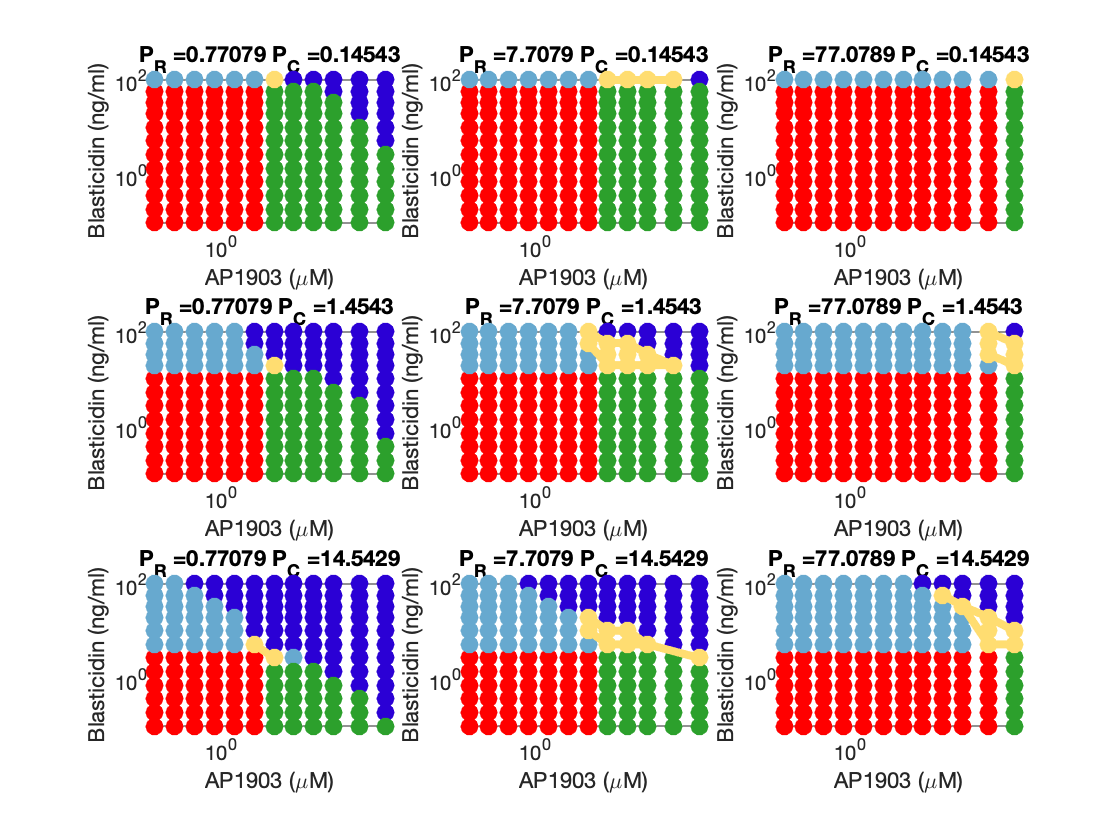

close all;
figure(1)
Size = 8.5;
[k1,k2] = ndgrid(1:length(power_R) ,1:length(power_C));

parfor a =1:numel(k1)
    
    matrix_row_PD = find(Pure_Death(:,3) == 10.^power_R(k1(a)));
    matrix_col_PD = find(Pure_Death(:,4) == 10.^power_C(k2(a)));
    index_PD = intersect(matrix_row_PD,matrix_col_PD);
    AP1903_PD{a}= Pure_Death(index_PD,1);
    BLAST_PD{a}= Pure_Death(index_PD,2);
    
    matrix_row_PG = find(Pure_Growth(:,3) == 10.^power_R(k1(a)));
    matrix_col_PG = find(Pure_Growth(:,4) == 10.^power_C(k2(a)));
    index_PG = intersect(matrix_row_PG,matrix_col_PG);
    AP1903_PG{a}= Pure_Growth(index_PG,1);
    BLAST_PG{a}= Pure_Growth(index_PG,2);
    
    matrix_row_MU = find(mono_unstable(:,3) == 10.^power_R(k1(a)));
    matrix_col_MU= find(mono_unstable(:,4) == 10.^power_C(k2(a)));
    index_MU = intersect(matrix_row_MU,matrix_col_MU);
    AP1903_MU{a}= mono_unstable(index_MU,1);
    BLAST_MU{a}= mono_unstable(index_MU,2);
    
    matrix_row_MS = find(mono_stable(:,3) == 10.^power_R(k1(a)));
    matrix_col_MS= find(mono_stable(:,4) == 10.^power_C(k2(a)));
    index_MS = intersect(matrix_row_MS,matrix_col_MS);
    AP1903_MS{a}= mono_stable(index_MS,1);
    BLAST_MS{a}= mono_stable(index_MS,2);
    
    matrix_row_BIS = find(bi_stable(:,3) == 10.^power_R(k1(a)));
    matrix_col_BIS= find(bi_stable(:,4) == 10.^power_C(k2(a)));
    index_BIS = intersect(matrix_row_BIS,matrix_col_BIS);
    AP1903_BIS{a}= bi_stable(index_BIS,1);
    BLAST_BIS{a}= bi_stable(index_BIS,2);
    
end

save("ParamMatrix_144dots_9sqrs",'AP1903_PD','BLAST_PD','AP1903_PG','BLAST_PG','AP1903_MU','BLAST_MU','AP1903_MS','BLAST_MS',...
    'AP1903_BIS','BLAST_BIS','ratemono_unstable','ratemono_stable','ratebi_unstable','ratebi_stable','ratePure_Death','ratePure_Growth')

for  a =1:numel(k1)
    subplot(3,3,a)
    plot(BLAST_PD{a},AP1903_PD{a},'ko','MarkerSize',Size,'MarkerFaceColor',[43,0,213]./255,'MarkerEdgeColor',[43,0,213]./255)
    hold on
    plot(BLAST_PG{a},AP1903_PG{a},'ko','MarkerSize',Size,'MarkerFaceColor',[255,0,0]./255,'MarkerEdgeColor',[255,0,0]./255)
    
    plot(BLAST_MU{a},AP1903_MU{a},'ko','MarkerSize',Size,'MarkerFaceColor',[103,169,207]./255,'MarkerEdgeColor',[103,169,207]./255)
    
    plot(BLAST_MS{a},AP1903_MS{a},'ko','MarkerSize',Size,'MarkerFaceColor',[44,160,44]./255,'MarkerEdgeColor',[44,160,44]./255)
  

    
% plot a nice boundary
 y = AP1903_BIS{a};
 x = BLAST_BIS{a};
class_label = unique(x);
upper_boundary = zeros(size(class_label));
lower_boundary = zeros(size(class_label));
for idx = 1:numel(class_label)
        class = y(x == class_label(idx));
        upper_boundary(idx) = max(class);
        lower_boundary(idx) = min(class);
end


    left_boundary = y(x == class_label(1));
    right_boundary = y(x == class_label(end));
    plot(class_label(1)*ones(size(left_boundary)),left_boundary,'Color',[255,221,113]./255,'LineWidth',4)
    plot(class_label,upper_boundary,'Color',[255,221,113]./255,'LineWidth',4)
    plot(class_label(end)*ones(size(right_boundary)),right_boundary,'--','Color',[255,221,113]./255,'LineWidth',4)
    plot(class_label,lower_boundary,'Color',[255,221,113]./255,'LineWidth',4)


    plot(BLAST_BIS{a},AP1903_BIS{a},'ko','MarkerSize',Size,'MarkerFaceColor',[255,221,113]./255,'MarkerEdgeColor',[255,221,113]./255)
    ylabel('Blasticidin (ng/ml)')
    xlabel('AP1903 (\muM)')
    title(['P_R =',num2str(10.^power_R(k1(a))),' P_C =',num2str(10.^power_C(k2(a)))])
    ax = gca;
    ax.XScale = 'log';
    ax.YScale = 'log';
    
   
end

auxins = logspace(-2,2.5,100);

figure(2)
rVa_G = double(subs(ratePure_Growth(20),'A',auxins));

rVa_G =     0.0294    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0296    0.0296    0.0296    0.0296    0.0297    0.0297    0.0297    0.0298    0.0298    0.0299    0.0299    0.0300    0.0301    0.0301    0.0302    0.0303    0.0304    0.0305    0.0306    0.0307    0.0308    0.0310    0.0311    0.0313    0.0314    0.0316    0.0318    0.0320    0.0322    0.0324    0.0327    0.0329    0.0332    0.0334    0.0337    0.0339    0.0342    0.0345    0.0347    0.0350    0.0352    0.0355


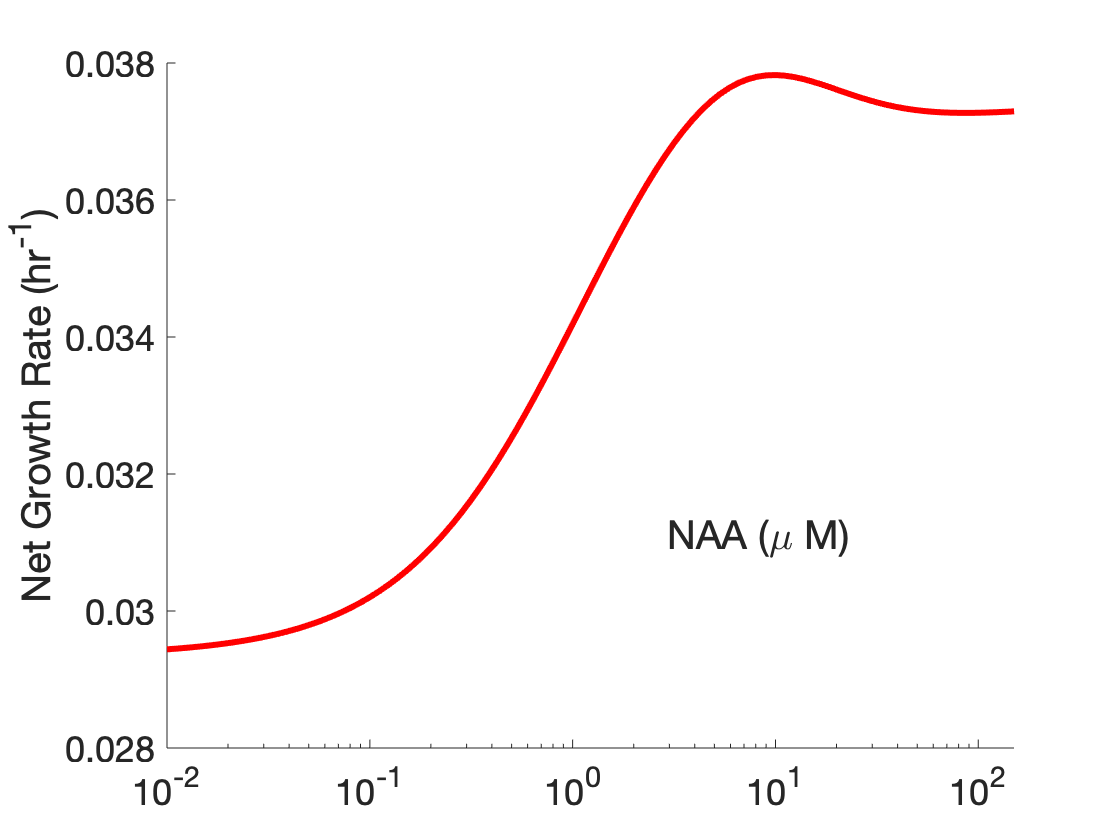

semilogx(auxins, rVa_G,'r-','LineWidth',3)

xlh = xlabel('NAA (\mu M)');
xlh.Position(2) = xlh.Position(2) + 0.003;
xlh.Position(1) = xlh.Position(1) + 5;

ylabel({'Net Growth Rate (hr^{-1})'})
ax1 = gca;
ax1.FontSize = 18;
ax1.XAxisLocation = 'origin';
% ax1.YAxisLocation = 'origin';
% ax.FontWeight = 'bold';
box off

xlim([-1,150])
% ylim([-.04,.03])
xticks([.01, .1, 1, 10, 100])
xtickformat('%.1e')

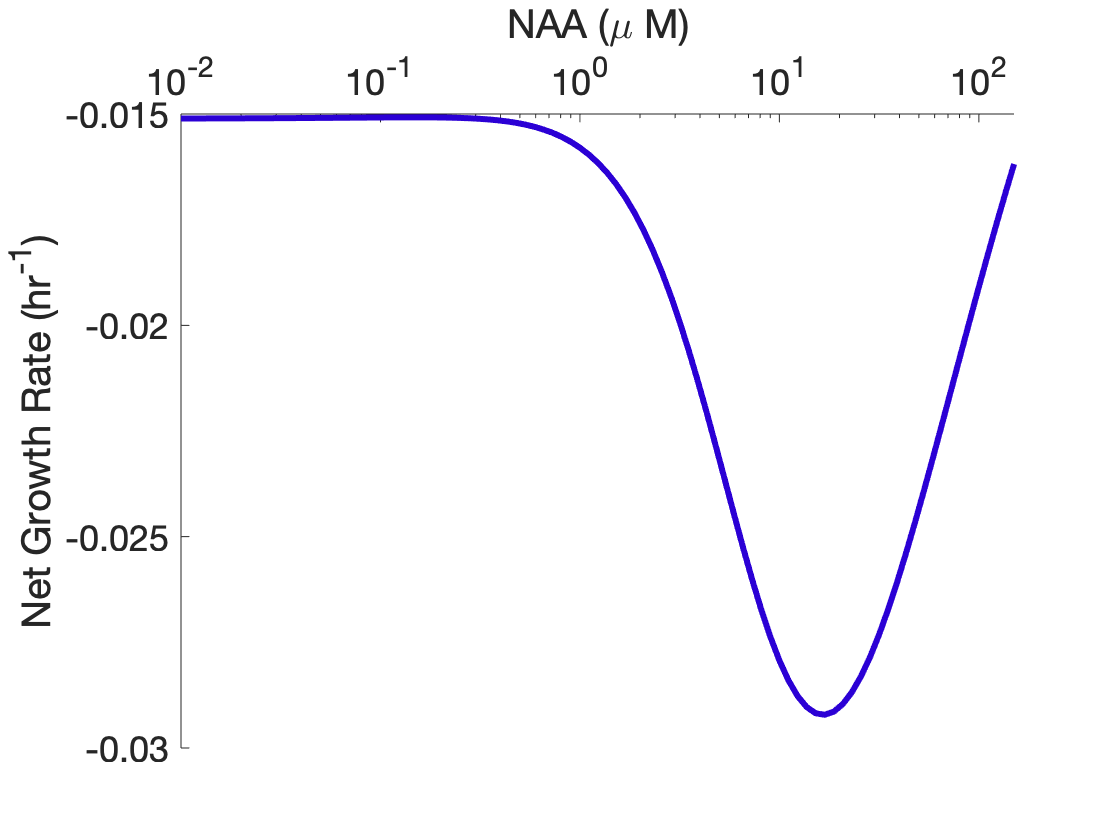


figure(3)
rVa_PD = double(subs(ratePure_Death(20),'A',auxins));
semilogx(auxins, rVa_PD,'Color',[43,0,213]./255,'LineWidth',3)
xlh = xlabel('NAA (\mu M)');
% xlh.Position(2) = xlh.Position(2) + 0.003;
% xlh.Position(1) = xlh.Position(1) + 5;

ylabel({'Net Growth Rate (hr^{-1})'})
ax1 = gca;
ax1.FontSize = 18;
ax1.XAxisLocation = 'origin';
% ax1.YAxisLocation = 'origin';
% ax.FontWeight = 'bold';
box off

xlim([-1,150])
% ylim([-.04,.03])
xticks([.01, .1, 1, 10, 100])
xtickformat('%.1e')


figure(4)
rVa_MU = double(subs(ratemono_unstable(80),'A',auxins));

rVa_MU =    -0.0134   -0.0134   -0.0134   -0.0134   -0.0134   -0.0134   -0.0134   -0.0134   -0.0134   -0.0134   -0.0134   -0.0134   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0133   -0.0132   -0.0132   -0.0132   -0.0131   -0.0131   -0.0131   -0.0130   -0.0130   -0.0129   -0.0129   -0.0128   -0.0128   -0.0127   -0.0126   -0.0125   -0.0124   -0.0123   -0.0122   -0.0120   -0.0119   -0.0117   -0.0116   -0.0114   -0.0112   -0.0110   -0.0107   -0.0105   -0.0102   -0.0099   -0.0095   -0.0092   -0.0088


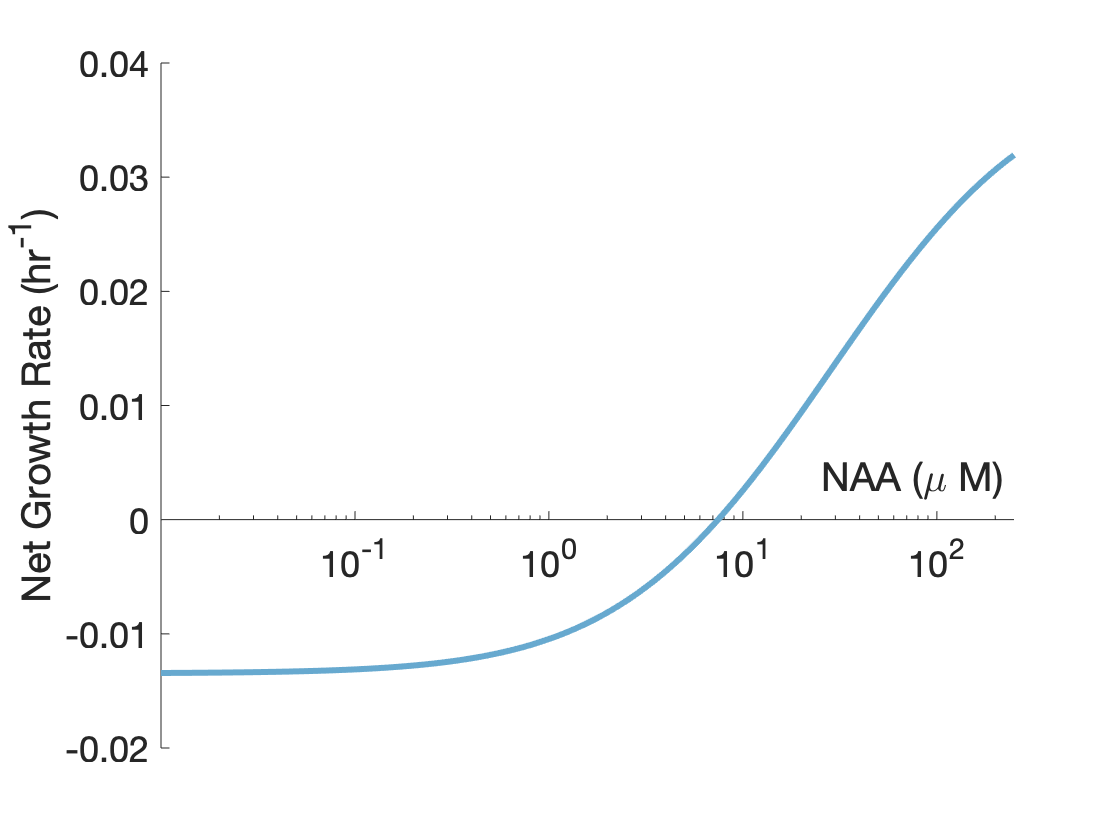

semilogx(auxins, rVa_MU,'Color',[103,169,207]./255,'LineWidth',3)

xlh = xlabel('NAA (\mu M)');
% xlh.Position(2) = xlh.Position(2) + 0.003;
% xlh.Position(1) = xlh.Position(1) + 5;

ylabel({'Net Growth Rate (hr^{-1})'})
ax1 = gca;
ax1.FontSize = 18;
ax1.XAxisLocation = 'origin';
% ax1.YAxisLocation = 'origin';
% ax.FontWeight = 'bold';
box off

xlim([-1,250])
% ylim([-.04,.03])
xticks([.01, .1, 1, 10, 100])
xtickformat('%.1e')

figure(5)
rVa_MS = double(subs(ratemono_stable(80),'A',auxins));

rVa_MS =     0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0410    0.0409    0.0409    0.0409    0.0409    0.0409    0.0409    0.0409    0.0408    0.0408    0.0408    0.0407    0.0407    0.0406    0.0406    0.0405    0.0405    0.0404    0.0403    0.0402    0.0401    0.0399    0.0398    0.0396    0.0394    0.0392


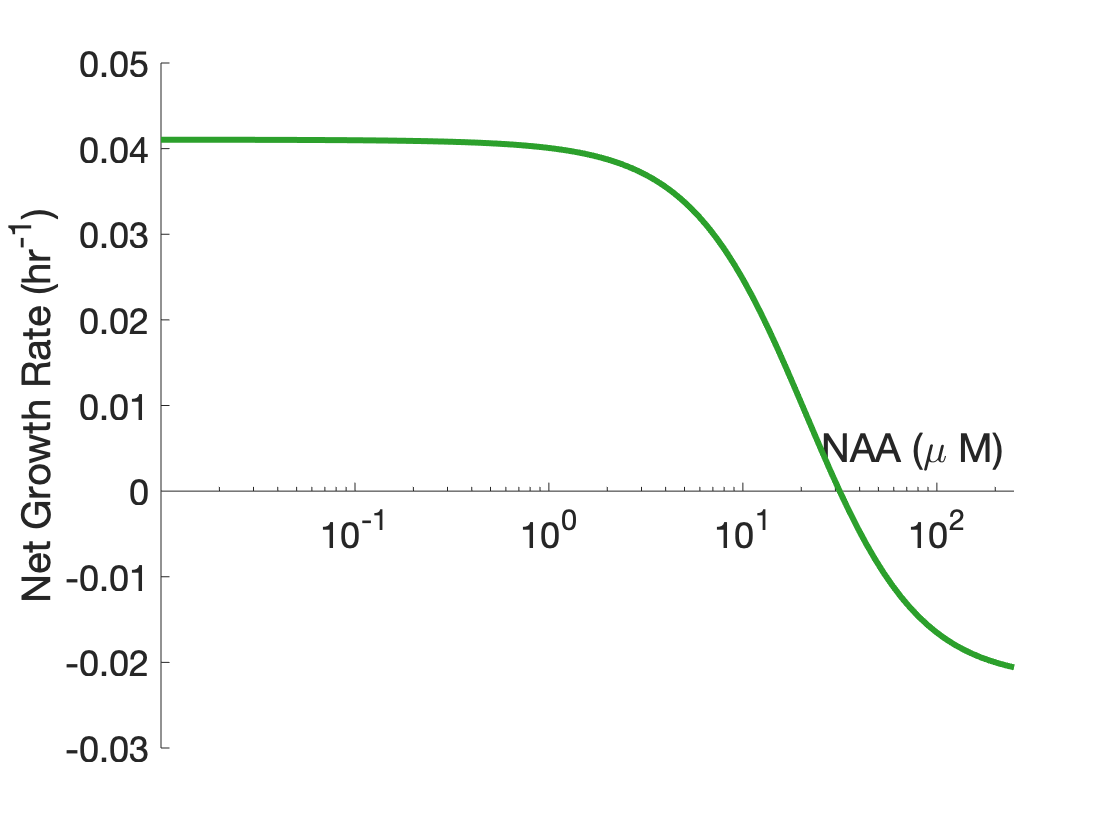

semilogx(auxins, rVa_MS,'Color',[44,160,44]./255,'LineWidth',3)
xlh = xlabel('NAA (\mu M)');
% xlh.Position(2) = xlh.Position(2) + 0.003;
% xlh.Position(1) = xlh.Position(1) + 5;

ylabel({'Net Growth Rate (hr^{-1})'})
ax1 = gca;
ax1.FontSize = 18;
ax1.XAxisLocation = 'origin';
% ax1.YAxisLocation = 'origin';
% ax.FontWeight = 'bold';
box off

xlim([-1,250])
% ylim([-.04,.03])
xticks([.01, .1, 1, 10, 100])
xtickformat('%.1e')



figure(6)
rVa_BS = double(subs(ratebi_stable(30),'A',auxins));

rVa_BS =    -0.0109   -0.0109   -0.0109   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0107   -0.0107   -0.0107   -0.0107   -0.0106   -0.0106   -0.0106   -0.0105   -0.0105   -0.0104   -0.0104   -0.0103   -0.0103   -0.0102   -0.0101   -0.0100   -0.0099   -0.0098   -0.0097   -0.0096   -0.0095   -0.0093   -0.0092   -0.0090   -0.0088   -0.0086   -0.0084   -0.0081   -0.0079   -0.0076   -0.0073   -0.0069   -0.0066   -0.0062   -0.0058   -0.0054   -0.0049   -0.0044


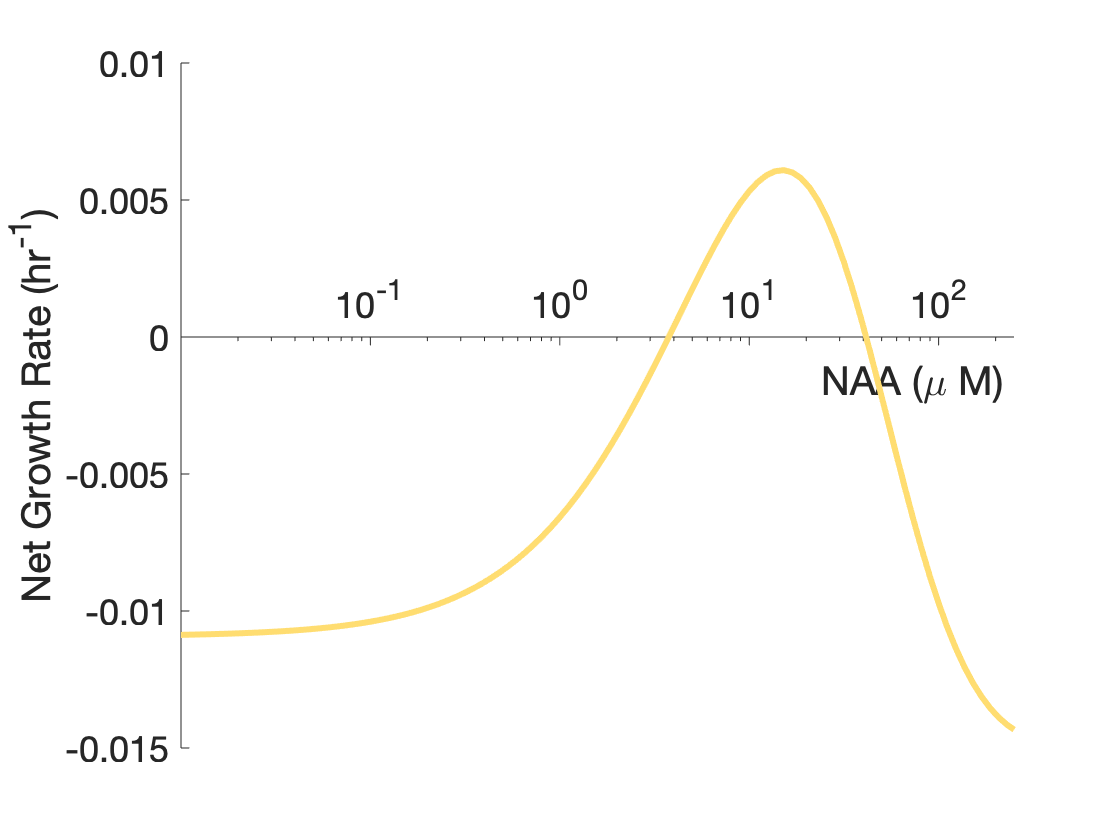

semilogx(auxins, rVa_BS,'Color',[255,221,113]./255,'LineWidth',3)
xlh = xlabel('NAA (\mu M)');
% xlh.Position(2) = xlh.Position(2) + 0.003;
% xlh.Position(1) = xlh.Position(1) + 5;

ylabel({'Net Growth Rate (hr^{-1})'})
ax1 = gca;
ax1.FontSize = 18;
ax1.XAxisLocation = 'origin';
% ax1.YAxisLocation = 'origin';
% ax.FontWeight = 'bold';
box off

xlim([-1,250])
% ylim([-.04,.03])
xticks([.01, .1, 1, 10, 100])
xtickformat('%.1e')